## Installation

After downloading MacaulayLab

% addpath(genpath(pwd));
% savepath;

## Help and documentation

It is easy to access the documentation of the different functions.

help nbmonomials

 nbmonomials   Number of monomials.
    s = nbmonomials(d,n) returns the number of monomials in the 
    monomial basis for n variables and maximum total degree d.
 
    s = nbmonomials(...,blocksize) takes into account the blocksize.
 
    See also monomials.



## Quick start		

The easiest way to represent a system of multivariate polynomials is by con- sidering a matrix for every polynomial of the system, where the first column corresponds to the coefficients of the polynomials and the remaining columns represent the powers of the variables in the corresponding monomials. 

p1 = [2 2 0; -3 0 1; 1 0 0];
p2 = [1 2 0; 1 0 2; 16 0 0];
eqs = {p1, p2};
system = systemstruct(eqs);			

Similarly, a rectangular multiparameter eigenvalue problem can be represented by a cell array that contains all its coefficient matrices and a matrix that describes the monomial that belongs to each coefficient matrix. 

A00 = randn(4,3); A10 = randn(4,3); A01 = randn(4,3);
mat = {A00, A10, A01};
supp = [0 0; 1 0; 0 1];
mep = mepstruct(mat,supp);

Solving these problems only takes one additional line of code each.

commonroots = macaulaylab(system)

commonroots =    1.4825 - 1.9552i  -0.7500 - 3.8649i
   1.4825 + 1.9552i  -0.7500 + 3.8649i
  -1.4825 - 1.9552i  -0.7500 + 3.8649i
  -1.4825 + 1.9552i  -0.7500 - 3.8649i


eigenvalues = macaulaylab(mep)

eigenvalues =    0.1211 + 1.4665i   1.1560 + 2.8954i
   0.1211 - 1.4665i   1.1560 - 2.8954i
   0.8753 + 0.0000i  -0.9575 + 0.0000i
   1.3702 + 0.0000i   1.2985 + 0.0000i
  -0.3455 + 0.4007i  -0.3281 + 0.1838i
  -0.3455 - 0.4007i  -0.3281 - 0.1838i


The solutions are in a solutionstruct. You can acces the numerical values via num.

whos("commonroots")

  Name             Size            Bytes  Class             Attributes

  commonroots      1x1               184  solutionstruct              



values = num(commonroots);
whos("values")

  Name        Size            Bytes  Class     Attributes

  values      4x2               128  double    complex   



## Other problem manipulations

Via expansion and contraction, it is possible to represent a polynomial in its matrix or row vector representation.

P = [1 2 0 0; 2 0 1 1; 3 0 0 0];
p = expansion(P)

p =      1     0     0     0     2     0     0     0     0     3


Q = contraction(p,2,3)				

Q =      3     0     0     0
     2     0     1     1
     1     2     0     0


The systemstruct constructor can also work with symbolic polynomials. 

syms x y;
p1 = 2*x^2 + 3*x*y;
p2 = x^2*y^3 - 1;
symboliceqs = {p1, p2};
system = systemstruct(symboliceqs)

system =      system of 2 univariate polynomials with maximum degree 0 

You can create random multivariate polynomial systems and multiparameter problems via randsystem and randmep.

system = randsystem(2,2,2)

system =      system of 2 multivariate polynomials with maximum total degree 2 

mep = randmep(2,2,5,4,[0 0; 1 0; 2 0; 1 1])

mep =      2-parameter eigenvalue problem with total degree 2 

complexsystem = randsystem(2,2,2,true)

complexsystem =      system of 2 multivariate polynomials with maximum total degree 2 

You can retrieve information from these problems.

disp(system)

     system of 2 multivariate polynomials with maximum total degree 2 


[s,dmax,n,di,nnze,k,l] = properties(system)

s = 2

dmax = 2

n = 2

di = 2×1 cell array
    {[2]}
    {[2]}


nnze = 2×1 cell array
    {[6]}
    {[6]}


k = 1

l = 1

info(mep)

     2-parameter eigenvalue problem with total degree 2 

        (A00 + A10 λ1+ A20 λ1^2 + A11 λ1λ2) z = 0 

    coefficient matrices are 5 x 4 matrices 
    sparsity factor is 0.67 


## Solving problems

### Step-by-step solution approach

Suppose that we want to solve x

p = [1 1 1 0; -3 0 0 0];
q = [1 2 0 0; -1 0 0 2; 1 1 0 1; -5 0 0 0];
r = [1 0 0 3; -2 1 1 0; 7 0 0 0];
system = systemstruct({p,q,r})

system =      system of 3 multivariate polynomials with maximum total degree 3 

The first step is, of course, to build the macaulay matrix.

M = macaulay(system,7);
size(M)

ans =    147   120


The standard approach is to compute a basis matrix of the right null space. You could use the direct approach (null), but the toolbox also includes much more efficient functions, like a sparse approach (nullsparsemacaulay). There is a wrapper function nullitermacaulay that takes care of this iteration.

Z = nullitermacaulay(system,7,"sparse");
size(Z)

ans =    120    12


To determine the number of affine solutions and gap, we can use gap. This allows us to perform a column compression when necessary.

[dgap,ma,gapsize] = gap(Z,3)

dgap = 3

ma = 6

gapsize = 1

Z = columncompr(Z,dgap,3)

Z =    -0.0838    0.0212   -0.1429    0.0326    0.0830   -0.0391
   -0.0726   -0.1323    0.0383    0.0426    0.0481    0.0195
   -0.1365    0.0110    0.0483    0.0145   -0.0495   -0.0407
   -0.1338    0.0629    0.0724   -0.0599   -0.0804   -0.0207
    0.0608   -0.1851   -0.0902   -0.2124   -0.4977    0.4621
   -0.0213   -0.2583   -0.2724   -0.3803   -0.3195    0.0754
   -0.0507   -0.2490   -0.3799   -0.4264   -0.0183   -0.3229
   -0.1966   -0.0327   -0.3842   -0.0907    0.1228   -0.2009
   -0.2515    0.0637   -0.4287    0.0977    0.2489   -0.1172
   -0.3077    0.1701   -0.4248    0.3768   -0.0646    0.5897


By setting up (generalized) multiplication maps, we can obtain the common roots of the problem.

K = monomials(3,3);
shifts = {[1 1 0 0],[1 0 1 0],[1 0 0 1]};
idx = 1:nbmonomials(2,3);
[A,B] = multmapnull(Z,K,shifts,idx);
eig(pinv(A{1})*B{1})

ans =   -2.3574 + 0.6899i
  -2.3574 - 0.6899i
  -2.0000 + 0.0000i
   3.0000 + 0.0000i
   1.8574 + 0.1762i
   1.8574 - 0.1762i


### Direct solution approach

Of course, there is a solver implemented that takes care of all these interme- diate steps and checks whether the right null space of the (block) Macaulay matrix can accommodate the shift polynomial. 

system = randsystem(3,3,3);
commonroots = macaulaylab(system)

commonroots =   10.0373 + 3.9906i   4.2360 + 4.4326i   1.3238 -15.2860i
  10.0373 - 3.9906i   4.2360 - 4.4326i   1.3238 +15.2860i
   2.0004 - 2.1682i  -2.8720 + 4.9501i   2.7168 + 0.2727i
   2.0004 + 2.1682i  -2.8720 - 4.9501i   2.7168 - 0.2727i
   0.2416 - 2.8716i  -2.8011 - 1.9229i  -0.9970 + 0.1342i
   0.2416 + 2.8716i  -2.8011 + 1.9229i  -0.9970 - 0.1342i
   1.2699 - 0.5799i   0.2502 - 0.2860i   0.7231 - 0.2590i
   1.2699 + 0.5799i   0.2502 + 0.2860i   0.7231 + 0.2590i
   0.3108 - 1.0403i  -0.2014 + 2.0044i  -1.4966 - 1.3178i
   0.3108 + 1.0403i  -0.2014 - 2.0044i  -1.4966 + 1.3178i
   1.1735 - 1.7182i  -1.0205 + 1.1608i  -2.2818 + 0.1546i
   1.1735 + 1.7182i  -1.0205 - 1.1608i  -2.2818 - 0.1546i
  -1.7271 + 0.0000i  -0.1360 + 0.0000i  -1.4753 + 0.0000i
  -0.1285 - 0.8527i   0.8208 + 0.8493i  -0.3108 - 0.1256i
  -0.1285 + 0.8527i   0.8208 - 0.8493i  -0.3108 + 0.1256i
  -2.8513 + 0.0000i   1.3379 + 0.0000i   2.8941 + 0.0000i
  -0.7428 + 0.0000i   2.8597 + 0.0000i  -0.9805 + 0.0000i


It is possible to add options to the solver via key-value pairs. A full list of the options can be found in the documentation. For example, create a verbose output.

commonroots = macaulaylab(system,verbose=true)

        __  __                       _               __       _     
       |  \/  | __ _  ___ __ _ _   _| | __ _ _   _  / /  __ _| |__  
       | \  / |/ _` |/ __/ _` | | | | |/ _` | | | |/ /  / _` | '_ \ 
       | |\/| | (_| | (_| (_| | |_| | | (_| | |_| / /__| (_| | |_) |       
       |_|  |_|\__,_|\___\__,_|\__,_|_|\__,_|\__, \____/\__,_|_.__/ 
                                             |___/                  

                               version 1.0.0                              

                 Copyright (c) 2024 -- Christof Vermeersch                                  
___________________________________________________________________________

                               PROBLEM INFO                                
     system of 3 multivariate polynomials with maximum total degree 3 

        p1(x1,...,x3) = 0     <- d1 = 3 
        p2(x1,...,x3) = 0     <- d2 = 3 
        p3(x1,...,x3) = 0     <- d3 = 3 

    sparsity factor is 1.00 
_______________________________

commonroots =   10.0373 - 3.9906i   4.2360 - 4.4326i   1.3238 +15.2860i
  10.0373 + 3.9906i   4.2360 + 4.4326i   1.3238 -15.2860i
   2.0004 + 2.1682i  -2.8720 - 4.9501i   2.7168 - 0.2727i
   2.0004 - 2.1682i  -2.8720 + 4.9501i   2.7168 + 0.2727i
   0.2416 - 2.8716i  -2.8011 - 1.9229i  -0.9970 + 0.1342i
   0.2416 + 2.8716i  -2.8011 + 1.9229i  -0.9970 - 0.1342i
  -2.8513 + 0.0000i   1.3379 + 0.0000i   2.8941 + 0.0000i
  -0.7428 + 0.0000i   2.8597 + 0.0000i  -0.9805 + 0.0000i
  -0.9942 - 0.8797i   2.2673 - 2.5700i   0.2356 - 0.7219i
  -0.9942 + 0.8797i   2.2673 + 2.5700i   0.2356 + 0.7219i
   0.3108 + 1.0403i  -0.2014 - 2.0044i  -1.4966 + 1.3178i
   0.3108 - 1.0403i  -0.2014 + 2.0044i  -1.4966 - 1.3178i
   0.6746 - 0.7781i  -0.0202 - 0.4065i  -0.0282 + 1.3140i
   0.6746 + 0.7781i  -0.0202 + 0.4065i  -0.0282 - 1.3140i
  -1.2527 + 0.0000i   0.0467 + 0.0000i   1.1133 + 0.0000i
   0.0877 + 0.0000i   1.4064 + 0.0000i  -1.0140 + 0.0000i
   1.1735 - 1.7182i  -1.0205 + 1.1608i  -2.2818 + 0.1546i


You can also set a maximum degree for the Macaulay matrix iteration. By default, the solver sets this maximum degree at 100, but lower values are recommended.

commonroots = macaulaylab(system,10)

commonroots =   10.0373 - 3.9906i   4.2360 - 4.4326i   1.3238 +15.2860i
  10.0373 + 3.9906i   4.2360 + 4.4326i   1.3238 -15.2860i
   0.2416 + 2.8716i  -2.8011 + 1.9229i  -0.9970 - 0.1342i
   0.2416 - 2.8716i  -2.8011 - 1.9229i  -0.9970 + 0.1342i
  -0.9942 + 0.8797i   2.2673 + 2.5700i   0.2356 + 0.7219i
  -0.9942 - 0.8797i   2.2673 - 2.5700i   0.2356 - 0.7219i
   2.0004 - 2.1682i  -2.8720 + 4.9501i   2.7168 + 0.2727i
   2.0004 + 2.1682i  -2.8720 - 4.9501i   2.7168 - 0.2727i
  -2.8513 + 0.0000i   1.3379 + 0.0000i   2.8941 + 0.0000i
   1.1735 - 1.7182i  -1.0205 + 1.1608i  -2.2818 + 0.1546i
   1.1735 + 1.7182i  -1.0205 - 1.1608i  -2.2818 - 0.1546i
  -1.7271 + 0.0000i  -0.1360 + 0.0000i  -1.4753 + 0.0000i
   0.3108 + 1.0403i  -0.2014 - 2.0044i  -1.4966 + 1.3178i
   0.3108 - 1.0403i  -0.2014 + 2.0044i  -1.4966 - 1.3178i
  -1.1641 + 0.2064i  -0.3030 - 0.3174i  -0.1967 + 0.7509i
  -1.1641 - 0.2064i  -0.3030 + 0.3174i  -0.1967 - 0.7509i
   1.2699 + 0.5799i   0.2502 + 0.2860i   0.7231 + 0.2590i


## Using other monomial order or polynomial basis

The toolbox is implemented independently from the monomial order and poly- nomial basis, which means that you can supply a certain monomial order or polynomial basis and use all the functions without any adaptations. 

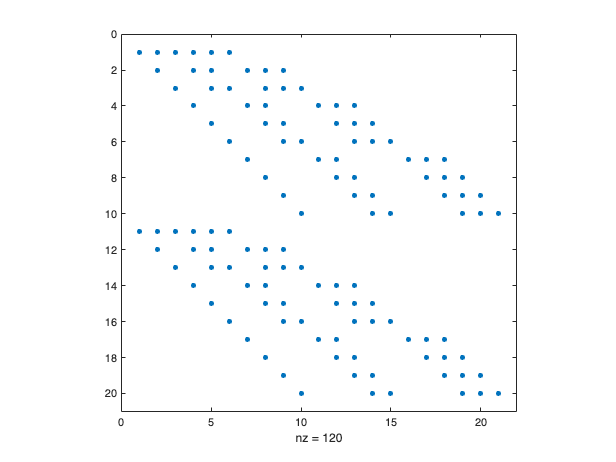

basis = @chebyshev;
order = @grlex;
system = randsystem(2,2,2);
N = macaulay(system,5);
M = macaulay(system,5,basis,order);
spy(N)

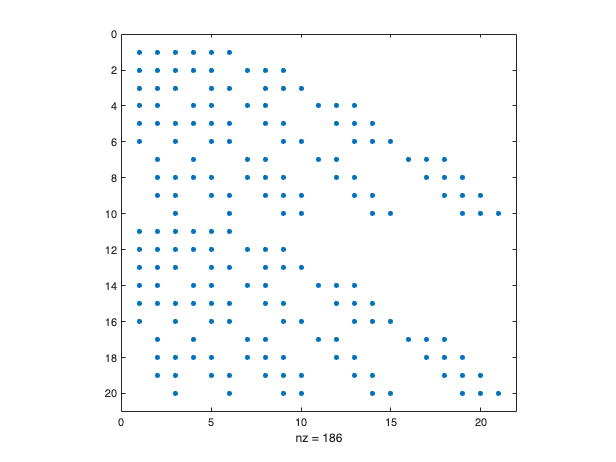

spy(M)